TOPHAT

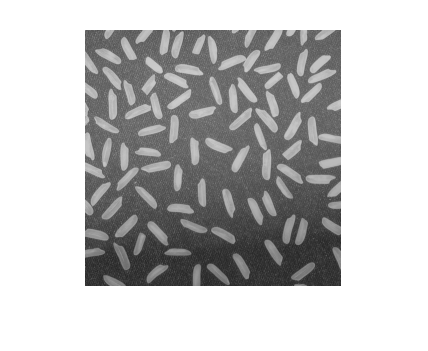

I = imread('rice.png');
imshow(I);

cellsize = 10;
SE = strel('disk', cellsize);

Tot el que sigui mes petit de radi 10 ho deixarà, la resta ho esborrarà. Deixa les parts birllants i elimina les ombres. Elimina la baixa frequencia. Deixa tota la part baixa del "barret"

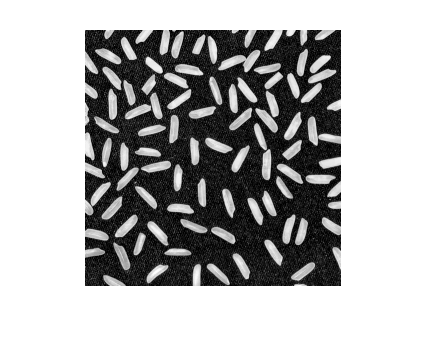

IF = imtophat(I, SE);
imshow(IF, []);

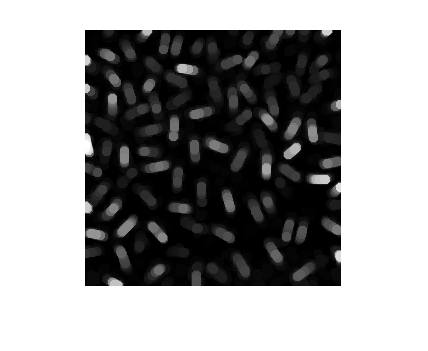

O = imopen(IF, strel('disk', 5));
imshow(O, []);

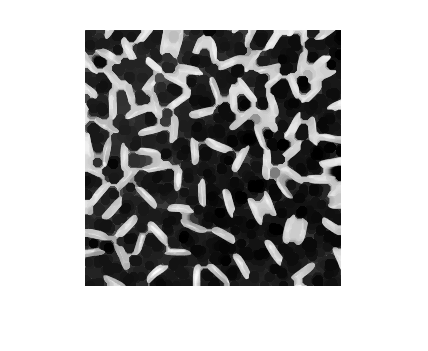

C = imclose(IF, strel('disk', 5));
imshow(C, []);

Openings i Closings

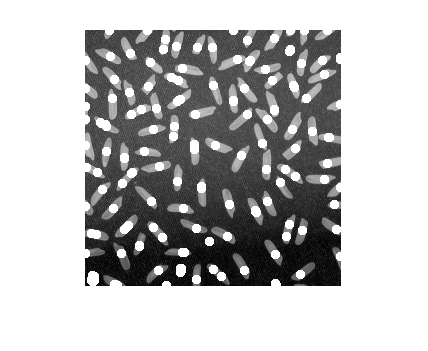

M = imregionalmax(O);
IS = I + uint8(M)*255;
imshow(IS, []);

Agafa la imatge filtrada i posa a 1 els pixels que corresponen a un màxim local, la imatge d'entrada ha d'estar filtrada. Surten rodones perque hem fet un fitre d'open amb un disk, per tant tots els punts del disk son marcats com a màxim.

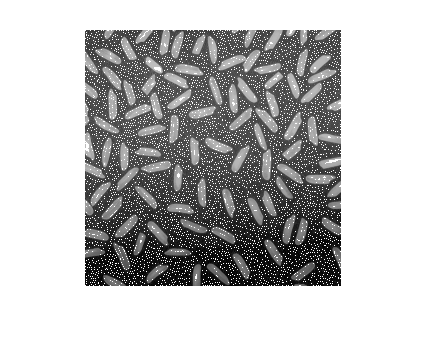

M = imregionalmax(I);
IS = I + uint8(M)*255;
imshow(IS, []);

En el segon punt, hem determinat el maxim d'una figura sense filtre el que fa que hi hagi molts més punts com a màxims locals.

-----

WATERSHED: tècnica que serveix per separar elements que haurien d'estar separades.

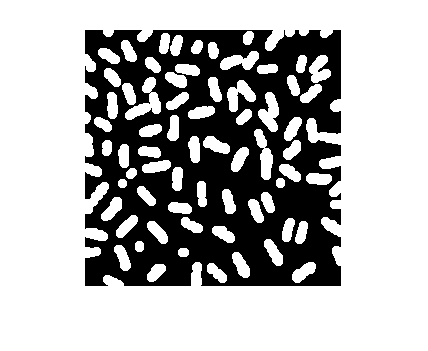

BW = O > 8;
imshow(BW, []); % Foreground

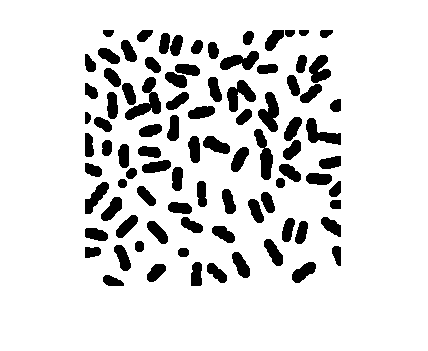

B = not(BW);
imshow(B, []); % Background

Per tal de fer el watershed, primer fem la transformada de la distancia:

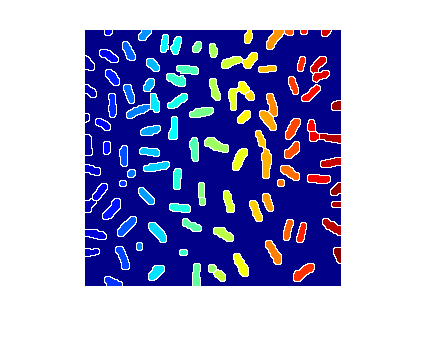

TD = bwdist(B, 'euclidean');
TD = -TD;
TD(B) = -Inf;
TDF = medfilt2(medfilt2(medfilt2(medfilt2(TD))));
WS = watershed(TDF);
RGB = label2rgb(WS);
imshow(RGB);

El medfilt2 es per treure els pous ja que té molts minims locals.

EXERCICI A ENTREGAR:

Agafar la imatge --- que son 3 imatges.

1r Treure el marc blanc de la imatge i la vorera gris

2n Marcar tots els components mitjançant la segmentació, marcant amb un .